# Laboratorio di Automatica (prova del 19 Giugno 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

June 19, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 3

In Fig. 3 è riportato lo schema di controllo di posizione di un motore elettrico a corrente continua che fa uso di un disturbance observer (DOB).

Il motore ha funzione di trasferimento:


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$. Il comando in tensione è fornito da un driver i cui livelli di saturazione di uscita sono sono pari a $\pm 10\,\mathrm{V}$. Il controllore di posizione è puramente proporzionale, con funzione di trasferimento:


$$C(s) \,=\, \frac{U(s)}{E(s)} \,=\, K_P\qquad\text{con}\qquad K_P = 1.2$$


dove l'errore di inseguimento $e$ (ingresso del controllore) si assume espresso in $\mathrm{[rad]}$.

Nel DOB, $P_n(s)$ rappresenta la funzione di trasferimento nominale dell'impianto da controllare, che nel seguito verrà assunta identica a $P(s)$, mentre $Q(s)$ è il seguente filtro passa-basso:


$$Q(s) \,=\, \frac{\omega_c^2}{s^2 + 2\delta\omega_c s + \omega_c^2}\qquad\text{con}\qquad \omega_c = 2\pi\,5\,\mathrm{rad/s}\,,\quad \delta = 1/\sqrt{2}$$


necessario per la fisica realizzabilità del DOB, e per la reiezione del rumore di misura $n$. 

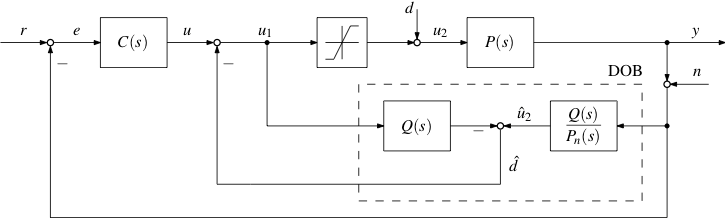

**Figura 3**: Sistema di controllo di posizione con DOB.

Si svolgano i seguenti punti:

1) Realizzare uno schema Simulink del sistema di controllo di Fig. 3.

*Soluzione*.

%   conversion gains
deg2rad = pi/180;
rad2deg = 180/pi;

%   motor params
km = 5.2;
Tm = 0.03;

numP = km;
denP = [Tm, 1, 0];

%   controller params
kp = 1.2;

%   DOB params - low-pass filter Q(s)
wc = 2*pi*5;
numQ = wc^2;
denQ = [1, 2/sqrt(2)*wc, wc^2];

%   DOB params - nominal plant Pn(s)
numPn = km;
denPn = [Tm, 1, 0];

%   DOB params - filter H(s)=Q(s)/Pn(s)
numH = conv(numQ, denPn);
denH = conv(denQ, numPn);

%    open Simulink model
open_system('ex3_sim1')

2) Simulare la risposta del sistema di controllo con un riferimento di posizione $r$ a gradino di ampiezza $A_r = 50\,\mathrm{deg}$ applicato in $t_r = 0\,\mathrm{s}$, e un disturbo $d$ a gradino di ampiezza $A_d = 5\,\mathrm{V}$, applicato in $t_d = 2\,\mathrm{s}$. Si imposti un tempo finale di simulazione adeguato (es. $4\,\mathrm{s}$).

*Soluzione*.

%    set reference params (amplitude & start time)
Ar = 50*deg2rad;  t0r = 0;  

%    set disturbance params (amplitude & start time)
Ad = 5;  t0d = 2;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.01', 'StopTime','4');

%    run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura Matlab gli andamenti dei seguenti segnali: 	

- plot 1: posizione misurata $y$ e riferimento $r$, entrambi espressi in $[\mathrm{deg}]$

- plot 2: errore di inseguimento $e$, espresso in $[\mathrm{deg}]$

- plot 3: disturbo $d$ e stima del disturbo $\hat{d}$, entrambi espressi in $[\mathrm{V}]$

Verificare che grazie alla presenza del DOB, il sistema di controllo è in grado di reiettare completamente il disturbo di carico costante, anche in assenza dell'azione integrale nel controllore.		

*Soluzione*.		

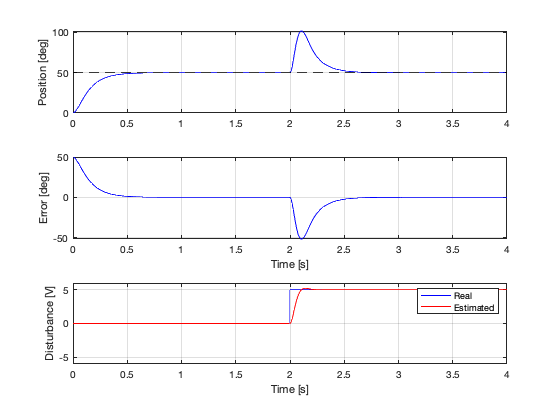

%   extract signas
t = simres.time;
th = simres.signals(1).values(:,1);
th_ref = simres.signals(1).values(:,2);
e = simres.signals(2).values;
d = simres.signals(3).values(:,1);
d_est = simres.signals(3).values(:,2);

%   plot results
figure;
subplot(3,1,1);
plot(t, th, 'b');
hold on;
plot(t, th_ref, 'k--');
grid on;
ylabel('Position [deg]');

subplot(3,1,2);
plot(t, e, 'b');
grid on;
ylabel('Error [deg]');
xlabel('Time [s]');

subplot(3,1,3);
plot(t, d, 'b');
hold on;
plot(t, d_est, 'r');
grid on;
ylabel('Disturbance [V]');
xlabel('Time [s]');
legend('Real', 'Estimated');
ylim([-6, 6]);